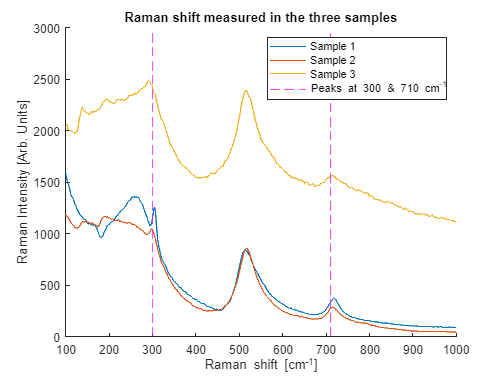

%clear crap
clear all

%importing data
data_1 = readtable("AIT/SAMPLE1_RAM.csv");
data_2 = readtable("AIT/SAMPLE2_RAM.csv");
data_3 = readtable("AIT/SAMPLE3_RAM.csv");

%extracting x & y coordinates
x_1 = table2array(data_1(:,1));
y_1 = table2array(data_1(:,2));
x_2 = table2array(data_2(:,1));
y_2 = table2array(data_2(:,2));
x_3 = table2array(data_3(:,1));
y_3 = table2array(data_3(:,2));

%plotting data
figure = plot(x_1,y_1);
hold on %plotting on the same graph
figure = plot(x_2,y_2);
figure = plot(x_3,y_3);

%plotting vertical lines
%to match up with data from papers
xline(710,"--m") %BaTiO3
xline(300,"--m") %BaTiO3

%labelling graph
xlabel("Raman shift [cm^{-1}]");
ylabel("Raman Intensity [Arb. Units]");
title("Raman shift measured in the three samples")
legend("Sample 1","Sample 2","Sample 3","Peaks at 300 & 710 cm^{-1}")

%limiting plots
xlim([100 1000])
ylim([0 3000])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

hold off %ending plot 